# Explore the dynamics of a DOUBLE compound **Pendulum**

In this example we're going to derive and then implement the equations of motion for a DOUBLE compound  pendulum. Specifically we're going to:

- Derive the equations of motion using's Newton's method

- Derive the reaction forces applied to the pendulum links.

The system that we're going to explore is shown below:

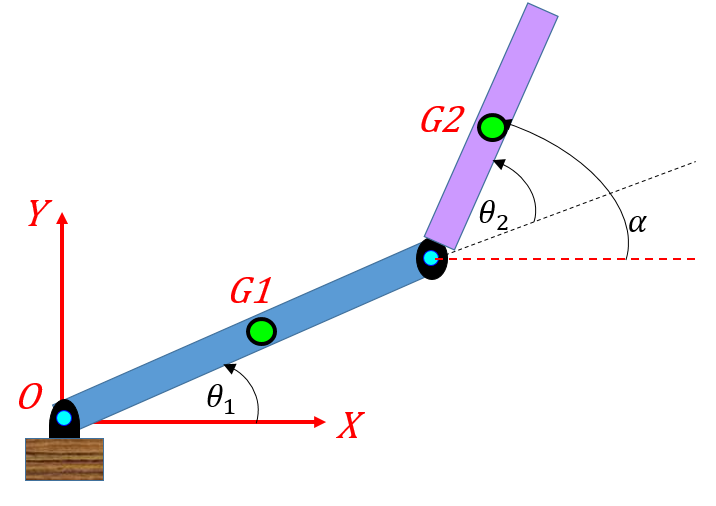

`Bradley Horton : 01-Aug-2016, bradley.horton@mathworks.com.au`

## Define some model parameters for LINK 1 and LINK 2:

Here's our double link pendulum:

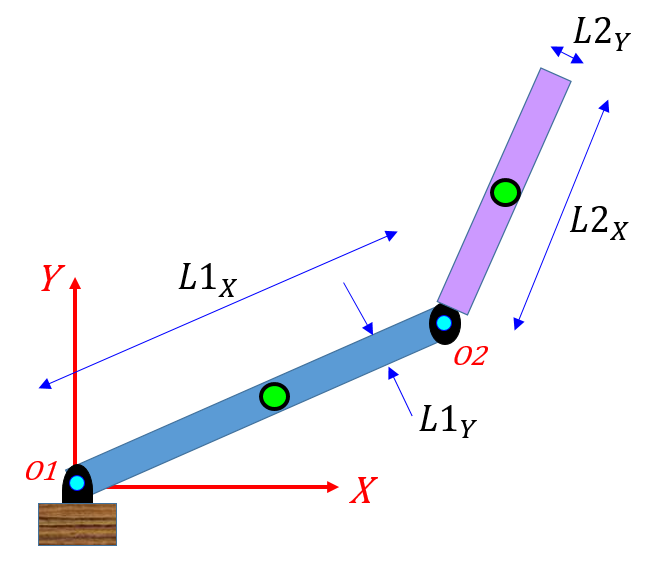   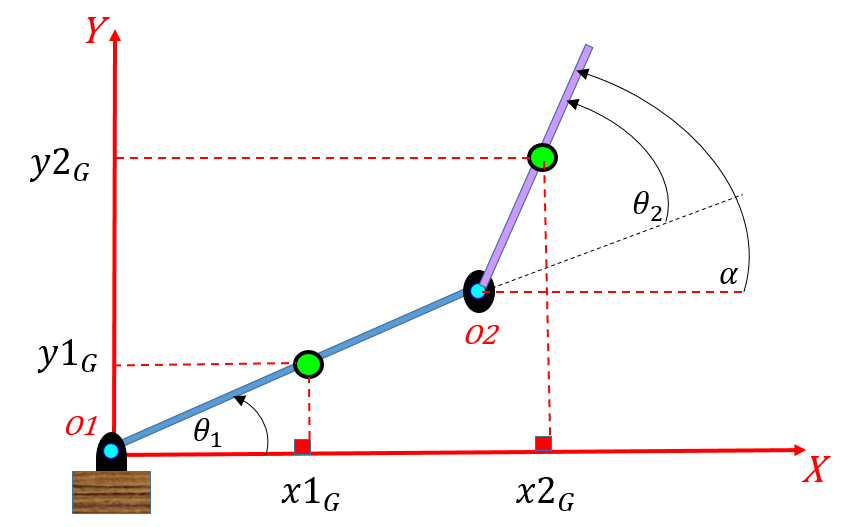

syms L1X_s    L2X_s 
syms m1_s     m2_s
syms t 
syms   theta1(t)  TH1_s  TH1D_s TH1DD_s
syms    alpha(t)  ALP_s  ALPD_s ALPDD_s

## The Equations of Motion:

Next let's apply Newton's 2nd law and derive the dynamic equations of motion for this system.  We will assume that each pivot point experiences viscous damping. A free body diagram for our system is shown below - note that gravity acts in the negative Y-direction.

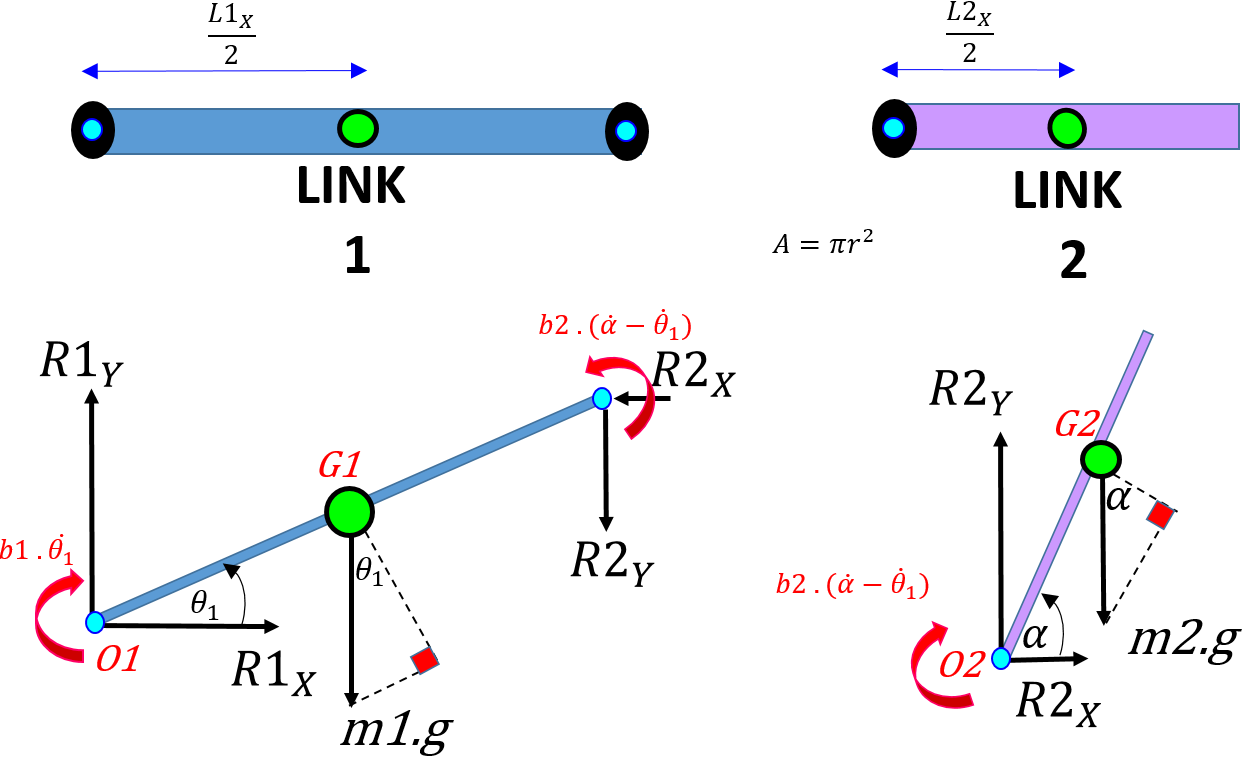

## **LINK_2:    Equations of motion and Reaction forces**

  

**Consider LINK 2:**

Taking the sum of moments about the ***Centre of mass of link2 G2***:


$$ I_{2G} \thinspace \ddot{\alpha} = \sum \tau
 = 
- b_2 .(\dot{\alpha}-\dot{\theta}_1)
\enspace + \enspace
R2_X . sin(\alpha).L2_X/2
\enspace - \enspace
R2_Y . cos(\alpha).L2_X/2
$$


Consider also the forces acting in the inertial(fixed) X-direction and Y-directions:


$$\matrix{
m_2 \thinspace \ddot{X}_{2G} = \sum F_X = R2_X  \cr
m_2 \thinspace \ddot{Y}_{2G} = \sum F_Y = R2_Y - m_2 \thinspace g  \cr
}$$
 

so we conclude that


$$\matrix{
R2_X  = m_2 \thinspace . \thinspace \ddot{X}_{2G}  \cr
R2_Y  = m_2 \thinspace . \thinspace \ddot{Y}_{2G} + m_2 \thinspace . \thinspace g
}
$$


Now let's use MATLAB to define these expressions for $R2_X$ and $R2_Y
$:

X2_G        = L1X_s*cos(theta1) + (L2X_s/2)*cos(alpha);
X2_G_d      = diff(X2_G, t) 

$$X2\_G\_d(t) = -\frac{{\mathrm{L2X}}_{s}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}-{\mathrm{L1X}}_{s}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)$$

X2_G_dd     = diff(X2_G, t, 2) 

$$X2\_G\_dd(t) = -\frac{{\mathrm{L2X}}_{s}\,\sin\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{2}-{\mathrm{L1X}}_{s}\,\cos\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}-{\mathrm{L1X}}_{s}\,\sin\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)-\frac{{\mathrm{L2X}}_{s}\,\cos\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{2}$$

Let's compute $\ddot{Y_G}(t)$ using MATLAB:

Y2_G        = L1X_s*sin(theta1) + (L2X_s/2)*sin(alpha);
Y2_G_d      = diff(Y2_G, t) 

$$Y2\_G\_d(t) = \frac{{\mathrm{L2X}}_{s}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial }{\partial t}\alpha \left(t\right)}{2}+{\mathrm{L1X}}_{s}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\theta_{1}\left(t\right)$$

Y2_G_dd     = diff(Y2_G, t, 2) 

$$Y2\_G\_dd(t) = \frac{{\mathrm{L2X}}_{s}\,\cos\left(\alpha \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\alpha \left(t\right)}{2}-\frac{{\mathrm{L2X}}_{s}\,\sin\left(\alpha \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\alpha \left(t\right)\right)}^{2}}{2}-{\mathrm{L1X}}_{s}\,\sin\left(\theta_{1}\left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta_{1}\left(t\right)\right)}^{2}+{\mathrm{L1X}}_{s}\,\cos\left(\theta_{1}\left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta_{1}\left(t\right)$$

And Let's define our $R2_X$ and $R2_Y$:

R2_X = m2_s*X2_G_dd;
R2_Y = m2_s*Y2_G_dd  + m2_s*9.81;

And let's convert our SYMFUN's into SYMS, 

THE_R2_X  = formula(R2_X); % R2_X(t);
THE_R2_Y  = formula(R2_Y); % R2_Y(t);

and then do some variable substitutions:

our_OLD_list_1 = [theta1,  diff(theta1,1),   diff(theta1, 2)];
our_new_list_1 = [ TH1_s,          TH1D_s,           TH1DD_s];

our_OLD_list_2 = [alpha,    diff(alpha,1),    diff(alpha, 2)];
our_new_list_2 = [ALP_s,           ALPD_s,           ALPDD_s];

THE_R2_X  = subs( THE_R2_X, [our_OLD_list_1, our_OLD_list_2], ...
                            [our_new_list_1, our_new_list_2]);
                          
THE_R2_Y  = subs( THE_R2_Y, [our_OLD_list_1, our_OLD_list_2], ...
                            [our_new_list_1, our_new_list_2]);
                        

At the end of this script I will automatically create a MATLAB function block for Simulink, that implements our expressions for $R2_X$ and $R2_Y$.  

RESULT_THE_R2_X = THE_R2_X;
RESULT_THE_R2_Y = THE_R2_Y;

## **LINK_1:    Equations of motion and Reaction forces**

     

**Consider LINK 1:**

Taking the sum of moments about the ***pivot point O1***:


$$ I_{10} \thinspace \ddot{\theta}_1 = \sum \tau
 = -m_1 \thinspace g \thinspace cos(\theta_1)L1_x/2 
\enspace - \enspace
b_1 \dot{\theta}_1 
\enspace + \enspace
R2_X.L1_x.sin(\theta_1)
\enspace - \enspace
R2_Y.L1_x.cos(\theta_1)
\enspace + \enspace
 b_2 .(\dot{\alpha}-\dot{\theta}_1)$$


Consider also the forces acting in the inertial(fixed) X-direction and Y-directions:


$$\matrix{
m_1 \thinspace \ddot{X}_{1G} = \sum F_X = R1_X  - R2_X\cr
m_1 \thinspace \ddot{Y}_{1G} = \sum F_Y = R1_Y - m_1 \thinspace g  - R2_Y\cr
}$$


so we conclude that


$$\matrix{
R1_X  = m_1 \thinspace . \thinspace \ddot{X}_{1G}  + R2_X \cr
R1_Y  = m_1 \thinspace . \thinspace \ddot{Y}_{1G} + m_1 \thinspace . \thinspace g + R2_Y
}
$$


When you look at the free body diagram for LINK 1, you see the complement of the R2 forces.  It is these R2 forces that provide the constraints that "connect" the motion of the two links.  I use the term "constraint" because the R2 forces are functions of $f(\theta_1, \dot{\theta}_1, \ddot{\theta}_1,
 \alpha, \dot{\alpha}, \ddot{\alpha})$.  

Now let's use MATLAB to define these expressions for $R1_X$ and $R1_Y
$:

X1_G        = (L1X_s/2)*cos(theta1);
X1_G_d      = diff(X1_G, t);
X1_G_dd     = diff(X1_G, t, 2); 

Y1_G        = (L1X_s/2)*sin(theta1);
Y1_G_d      = diff(Y1_G, t);
Y1_G_dd     = diff(Y1_G, t, 2); 

And Let's define our $R1_X$ and $R1_Y$:


$$\matrix{
R1_X  = m_1 \thinspace . \thinspace \ddot{X}_{1G}  + R2_X \cr
R1_Y  = m_1 \thinspace . \thinspace \ddot{Y}_{1G} + m_1 \thinspace . \thinspace g + R2_Y
}
$$


syms R2X_s R2Y_s

R1_X = m1_s*X1_G_dd  + R2X_s;
R1_Y = m1_s*Y1_G_dd  + R2Y_s + m1_s*9.81;

And let's convert our SYMFUN's into SYMS, 

THE_R1_X  = formula(R1_X); % R1_X(t);
THE_R1_Y  = formula(R1_Y); % R1_Y(t);

and then do some variable substitutions:

our_OLD_list_1 = [theta1,  diff(theta1,1),   diff(theta1, 2)];
our_new_list_1 = [ TH1_s,          TH1D_s,           TH1DD_s];

THE_R1_X  = subs( THE_R1_X, [our_OLD_list_1], ...
                            [our_new_list_1])

$$THE\_R1\_X = {\mathrm{R2X}}_{s}-m_{1,s}\,\left(\frac{{\mathrm{L1X}}_{s}\,\cos\left({\mathrm{TH}}_{1,s}\right)\,{{\mathrm{TH1D}}_{s}}^{2}}{2}+\frac{{\mathrm{L1X}}_{s}\,{\mathrm{TH1DD}}_{s}\,\sin\left({\mathrm{TH}}_{1,s}\right)}{2}\right)$$

                          
THE_R1_Y  = subs( THE_R1_Y, [our_OLD_list_1], ...
                            [our_new_list_1])

$$THE\_R1\_Y = {\mathrm{R2Y}}_{s}+\frac{981\,m_{1,s}}{100}-m_{1,s}\,\left(\frac{{\mathrm{L1X}}_{s}\,{{\mathrm{TH1D}}_{s}}^{2}\,\sin\left({\mathrm{TH}}_{1,s}\right)}{2}-\frac{{\mathrm{L1X}}_{s}\,{\mathrm{TH1DD}}_{s}\,\cos\left({\mathrm{TH}}_{1,s}\right)}{2}\right)$$

At the end of this script I will automatically create a MATLAB function block for Simulink, that implements our expressions for $R1_X$ and $R1_Y$.  

RESULT_THE_R1_X = THE_R1_X;
RESULT_THE_R1_Y = THE_R1_Y;

## Create Simulink blocks of our R1 and R2 equations:

First have a look at the symbols inside each equation:

symvar(  RESULT_THE_R2_X  )                          

$$ans = \left(\begin{array}{ccccccccc} {\mathrm{ALPDD}}_{s} & {\mathrm{ALPD}}_{s} & {\mathrm{ALP}}_{s} & {\mathrm{L1X}}_{s} & {\mathrm{L2X}}_{s} & {\mathrm{TH1DD}}_{s} & {\mathrm{TH1D}}_{s} & {\mathrm{TH}}_{1,s} & m_{2,s} \end{array}\right)$$

  and

symvar(  RESULT_THE_R2_Y  )

$$ans = \left(\begin{array}{ccccccccc} {\mathrm{ALPDD}}_{s} & {\mathrm{ALPD}}_{s} & {\mathrm{ALP}}_{s} & {\mathrm{L1X}}_{s} & {\mathrm{L2X}}_{s} & {\mathrm{TH1DD}}_{s} & {\mathrm{TH1D}}_{s} & {\mathrm{TH}}_{1,s} & m_{2,s} \end{array}\right)$$

and

symvar(  RESULT_THE_R1_X  )                          

$$ans = \left(\begin{array}{cccccc} {\mathrm{L1X}}_{s} & {\mathrm{R2X}}_{s} & {\mathrm{TH1DD}}_{s} & {\mathrm{TH1D}}_{s} & {\mathrm{TH}}_{1,s} & m_{1,s} \end{array}\right)$$

  and

symvar(  RESULT_THE_R1_Y  )

$$ans = \left(\begin{array}{cccccc} {\mathrm{L1X}}_{s} & {\mathrm{R2Y}}_{s} & {\mathrm{TH1DD}}_{s} & {\mathrm{TH1D}}_{s} & {\mathrm{TH}}_{1,s} & m_{1,s} \end{array}\right)$$

Now create the MATLAB function blocks for Simulink:

tf_i_should_create_SL_block = true;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_newt';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
     new_system(MODEL_NAME)
    open_system(MODEL_NAME)      
    
    % the R1X and R1Y equations
    INPUT_VAR_ORDER = {'L1X_s', 'm1_s', 'R2X_s','R2Y_s'...
                      'TH1DD_s', 'TH1D_s', 'TH1_s'}; 
                  
    matlabFunctionBlock( [MODEL_NAME,'/THE_R1_forces'], ...
                         RESULT_THE_R1_X, RESULT_THE_R1_Y, ...
                        'Optimize',false, ...
                        'Vars', INPUT_VAR_ORDER, ...
                        'Outputs', {'R1_X','R1_Y'}   );
                     
    % the R2X and R2Y equations
    INPUT_VAR_ORDER = {'L1X_s',  'L2X_s',  'm2_s', ...
                      'TH1DD_s', 'TH1D_s', 'TH1_s', ...
                      'ALPDD_s', 'ALPD_s', 'ALP_s'}; 
                  
    matlabFunctionBlock( [MODEL_NAME,'/THE_R2_forces'], ...
                         RESULT_THE_R2_X, RESULT_THE_R2_Y, ...
                         'Optimize',false, ...
                         'Vars', INPUT_VAR_ORDER, ...
                         'Outputs', {'R2_X','R2_Y'}   );              
end

## Implement and solve these equations of motion:

Although we could use MATLAB to numerically solve our system of ODEs, an alternate approach would be to use Simulink.  The Simulink model called <`bh_DBL_NEWT_compound_pendulum.slx`> implements our equations of motion.  Here are a few comments on this model:

- before running the Simulink model, run the script called <`bh_parameters_for_DOUBLE_compound_pendulum.mlx`> to load parameters (eg: inertias, initial conditions, etc) into the MATLAB workspace.

- In addition to implementing our hand derived equations of motion, we have also created a Simscape Multibody of the same 2 link manipulator.  We compare the results of our hand derivation to the Simscape model.